% give this simulation a name
SimulationName='Simulation_AfterRivisingFunctions_20231208';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/';
% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_AfterRivisingFunctions_20231208/'

cd(filepath)
mkdir('Simulated_data')

% 5. define the double exponential decay parameters and other parameters in
% the simulation

p1_samples=0.4:0.01:0.6; % simulate the p1 range
tau1=2.14; % tau1 
tau2=0.69; % tau2

afterpulse_ratio=0.0032; 

SS_samples=100000:50000:1000000; % simulated sample size range.


% collect the fitted p1 data

% savename_postfix = 'Results_20231210_1_';
% % or
% savename_postfix = 'Results_20231210_2_';
% or
savename_postfix = 'Results_20231218_3_';

SS_samples=100000:50000:800000; % simulated sample size range

% initialize the calculated p1, tau, and chi2 matrix
p1_mean_all = zeros(length(SS_samples), length(p1_samples));
p1_std_all = zeros(length(SS_samples), length(p1_samples));

tau_mean_all = zeros(length(SS_samples), length(p1_samples));
tau_std_all = zeros(length(SS_samples), length(p1_samples));

for i = 1:length(p1_samples)
    p1=p1_samples(i);
    savename = [savename_postfix, num2str(i), '.mat']; 
    load(savename) % for each p1 condition, load the saved file, calculate the p1 and mean
    for j = 1:length(SS_samples)
        p1_mean_all(j,i) = mean(p1_fitted(:,j)); % mean p1
        p1_std_all(j,i) = std(p1_fitted(:,j)); % std p1

        tau_mean_all(j,i) = mean(tau_empTrunc(:,j)); % mean p1
        tau_std_all(j,i) = std(tau_empTrunc(:,j)); % std p1

    end
end


% 6. plot the heatmap of fitted p1 and empirical lifetime
% load('Tau_SensorOnly.mat')
% load('Tau_Sensor_autoF.mat')
load('Tau_final.mat')


## **For figure 2.**

## **Calculate the minimal detectable difference based on the standard deviation of the simulated samples under each p1/photon count conditons.**

## **There are 2 sections for this part.**

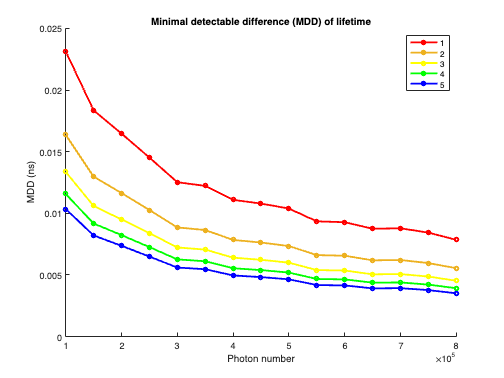


% 1. calculate the minimal detectable difference with average std under a
% certain photon count condition

% tau_std_mean_SS = zeros(1, length(SS_samples)); % initializing the mean standard deviation vector
tau_MDD_SS = zeros(1, length(SS_samples)); % initializing the minimal detectable difference vector
tau_MDD_SS_plot = []; % collecting the MDD vectors under each photon count condition
Colors = {'red', [0.9290 0.6940 0.1250], 'yellow', 'green', 'blue'};
legends = {'1', '2', '3', '4', '5'};
p1_plot = 0.5;

figure

for n_samples = 1:5 % assuming there are 1 or 2 or ... or 5 pairs of sampling for real experiments

%     for i = 1: length(SS_samples)
%         
%         tau_std_mean_SS(i) = mean(tau_std_all(i,:)); % the mean standard deviation under each photon number condition
%     end

%     tau_MDD_SS = tau_std_mean_SS*3.96/sqrt(n_samples); % calculate the MDD

    tau_std = tau_std_all(:,find(p1_samples == p1_plot));
    tau_MDD_SS = tau_std*3.96/sqrt(n_samples);
    eval(['tau_MDD_SS', '_', num2str(n_samples), '=tau_MDD_SS;'])

    tau_MDD_SS_plot = [tau_MDD_SS_plot tau_MDD_SS];% collecting the MDD vectors under each photon count condition
    plot(SS_samples,tau_MDD_SS, '-o','MarkerSize', 4, 'LineWidth', 2, 'Color', Colors{n_samples})
    hold on
end

legend(legends)
title('Minimal detectable difference (MDD) of lifetime')
xlabel('Photon number')
ylabel('MDD (ns)')
box off

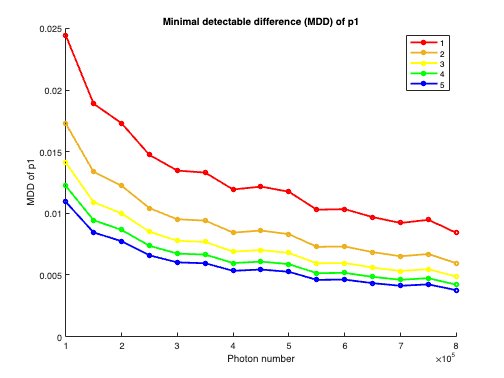

% 2. Calculate the minimal detectable difference with average std under a
% certain photon count condition;
% The process is same as what's for tau but instead use the fitted p1.

% p1_std_mean_SS = zeros(1, length(SS_samples));
p1_MDD_SS = zeros(1, length(SS_samples));
p1_MDD_SS_plot = [];
Colors = {'red', [0.9290 0.6940 0.1250], 'yellow', 'green', 'blue'};
legends = {'1', '2', '3', '4', '5'};
p1_plot = 0.5;

figure

for n_samples = 1:5

%     for i = 1: length(SS_samples)
%         
%         p1_std_mean_SS(i) = mean(p1_std_all(i,:));
%     end
%     p1_MDD_SS = p1_std_mean_SS*3.96/sqrt(n_samples);

    p1_std = p1_std_all(:,find(p1_samples == p1_plot));
    p1_MDD_SS = p1_std*3.96/sqrt(n_samples);
    eval(['p1_MDD_SS', '_', num2str(n_samples), '=p1_MDD_SS;'])

%     scatter(SS_samples,tau_MDD_SS, 30, 'filled', 'MarkerFaceColor', Colors{n_samples})
%     hold on
    p1_MDD_SS_plot = [p1_MDD_SS_plot p1_MDD_SS];
    plot(SS_samples,p1_MDD_SS, '-o','MarkerSize', 4, 'LineWidth', 2, 'Color', Colors{n_samples})
    hold on
end

legend(legends)
title('Minimal detectable difference (MDD) of p1')
xlabel('Photon number')
ylabel('MDD of p1')
box off

Separability_p1 = zeros(length(SS_samples)-1, length(p1_samples));
Separability_tau = zeros(length(SS_samples)-1, length(p1_samples));

for j = 1:length(p1_samples)-1

    for i = 1:length(SS_samples)
        Separability_p1(i,j) = (abs(p1_mean_all(i,j) - p1_mean_all(i, j+1)))/sqrt(p1_std_all(i,j)^2 + p1_std_all(i, j+1)^2);
        Separability_tau(i,j) = (abs(tau_mean_all(i,j) - tau_mean_all(i, j+1)))/sqrt(tau_std_all(i,j)^2 + tau_std_all(i, j+1)^2);

    end

end

% The next twp sections are for running the statistical t test on the fitted
% p1 and empirical lifetime between three conditions (sensor only, sensor/autoF, final data)
savename_postfix = {};

p1_fitted_test05 = {};
tau_test05 = {};

savename_postfix{1} = 'Results_20231210_1_';
savename_postfix{2} = 'Results_20231210_2_';
savename_postfix{3} = 'Results_20231210_3_';

i = 11;
for j = 1:3
    savename = [savename_postfix{j}, num2str(i), '.mat'];
    load(savename)
    p1_fitted_test05{j} = p1_fitted;
    tau_test05{j} = tau_empTrunc;
end



t_test_p1 = {};
t_test_tau = {};
for j = 1:3
    t_test_p1{j} = zeros(1,15);
    t_test_tau{j} = zeros(1,15);
end

comparisons = {[1 2], [1 3], [2 3]};

for j = 1:3
    for i = 1:15
        t_test_p1{j}(i) = 15*ranksum(p1_fitted_test05{comparisons{j}(1)}(:,i), p1_fitted_test05{comparisons{j}(2)}(:,i));
        t_test_tau{j}(i) = 15*ranksum(tau_test05{comparisons{j}(1)}(:,i), tau_test05{comparisons{j}(2)}(:,i));
    end
end

% To run two-way anova in Prism, here I'm getting the data structured so
% that it's easy to copy the data into prism sheet
comparisons = {[1 2], [1 3], [2 3]};

p1_anova2_structured = {};
tau_anova2_structured = {};

for i = 1:3
    p1_anova2_structured{i} = [transpose(p1_fitted_test05{comparisons{i}(1)}) transpose(p1_fitted_test05{comparisons{i}(2)})];
    tau_anova2_structured{i} = [transpose(tau_test05{comparisons{i}(1)}) transpose(tau_test05{comparisons{i}(2)})];
end

